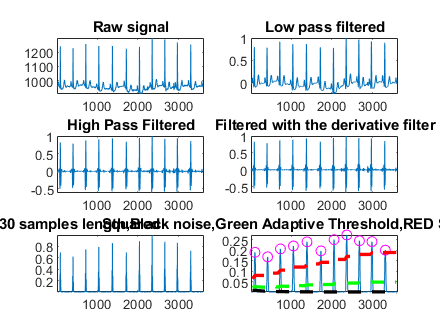

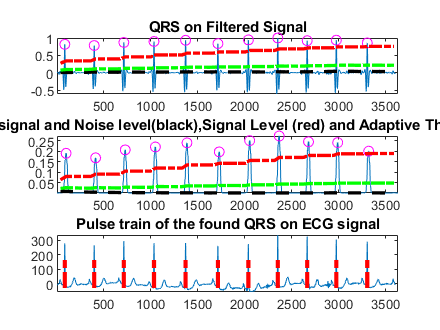

ans =     0.8183    0.7832    0.8721    0.8994    0.9336    0.8387    0.9466    1.0000    0.9225    0.9364    0.8590


pan_tompkin(Orig_Sig,200,1)

function [qrs_amp_raw,qrs_i_raw,delay,ecg_h]=pan_tompkin(ecg,fs,gr)

%% function [qrs_amp_raw,qrs_i_raw,delay]=pan_tompkin(ecg,fs)
% Complete implementation of Pan-Tompkins algorithm

%% Inputs

% ecg : raw ecg vector signal 1d signal
% fs : sampling frequency e.g. 200Hz, 400Hz and etc
% gr : flag to plot or not plot (set it 1 to have a plot or set it zero not
% to see any plots
%% Outputs
% qrs_amp_raw : amplitude of R waves amplitudes
% qrs_i_raw : index of R waves
% delay : number of samples which the signal is delayed due to the
% filtering
%% Method :

%% PreProcessing
% 1) Signal is preprocessed , if the sampling frequency is higher then it is downsampled
% and if it is lower upsampled to make the sampling frequency 200 Hz
% with the same filtering setups introduced in Pan
% tompkins paper (a combination of low pass and high pass filter 5-15 Hz)
% to get rid of the baseline wander and muscle noise. 

% 2) The filtered signal
% is derivated using a derivating filter to high light the QRS complex.

% 3) Signal is squared.4)Signal is averaged with a moving window to get rid
% of noise (0.150 seconds length).

% 5) depending on the sampling frequency of your signal the filtering
% options are changed to best match the characteristics of your ecg signal

% 6) Unlike the other implementations in this implementation the desicion
% rule of the Pan tompkins is implemented completely.

%% Decision Rule 
% At this point in the algorithm, the preceding stages have produced a roughly pulse-shaped
% waveform at the output of the MWI . The determination as to whether this pulse
% corresponds to a QRS complex (as opposed to a high-sloped T-wave or a noise artefact) is
% performed with an adaptive thresholding operation and other decision
% rules outlined below;

% a) FIDUCIAL MARK - The waveform is first processed to produce a set of weighted unit
% samples at the location of the MWI maxima. This is done in order to localize the QRS
% complex to a single instant of time. The w[k] weighting is the maxima value.

% b) THRESHOLDING - When analyzing the amplitude of the MWI output, the algorithm uses
% two threshold values (THR_SIG and THR_NOISE, appropriately initialized during a brief
% 2 second training phase) that continuously adapt to changing ECG signal quality. The
% first pass through y[n] uses these thresholds to classify the each non-zero sample
% (CURRENTPEAK) as either signal or noise:
% If CURRENTPEAK > THR_SIG, that location is identified as a QRS complex
% candidate and the signal level (SIG_LEV) is updated:
% SIG _ LEV = 0.125 CURRENTPEAK + 0.875 SIG _ LEV

% If THR_NOISE < CURRENTPEAK < THR_SIG, then that location is identified as a
% noise peak and the noise level (NOISE_LEV) is updated:
% NOISE _ LEV = 0.125CURRENTPEAK + 0.875 NOISE _ LEV
% Based on new estimates of the signal and noise levels (SIG_LEV and NOISE_LEV,
% respectively) at that point in the ECG, the thresholds are adjusted as follows:
% THR _ SIG = NOISE _ LEV + 0.25  (SIG _ LEV ? NOISE _ LEV )
% THR _ NOISE = 0.5 (THR _ SIG)
% These adjustments lower the threshold gradually in signal segments that are deemed to
% be of poorer quality.


% c) SEARCHBACK FOR MISSED QRS COMPLEXES - In the thresholding step above, if
% CURRENTPEAK < THR_SIG, the peak is deemed not to have resulted from a QRS
% complex. If however, an unreasonably long period has expired without an abovethreshold
% peak, the algorithm will assume a QRS has been missed and perform a
% searchback. This limits the number of false negatives. The minimum time used to trigger
% a searchback is 1.66 times the current R peak to R peak time period (called the RR
% interval). This value has a physiological origin - the time value between adjacent
% heartbeats cannot change more quickly than this. The missed QRS complex is assumed
% to occur at the location of the highest peak in the interval that lies between THR_SIG and
% THR_NOISE. In this algorithm, two average RR intervals are stored,the first RR interval is 
% calculated as an average of the last eight QRS locations in order to adapt to changing heart 
% rate and the second RR interval mean is the mean 
% of the most regular RR intervals . The threshold is lowered if the heart rate is not regular 
% to improve detection.

% d) ELIMINATION OF MULTIPLE DETECTIONS WITHIN REFRACTORY PERIOD - It is
% impossible for a legitimate QRS complex to occur if it lies within 200ms after a previously
% detected one. This constraint is a physiological one  due to the refractory period during
% which ventricular depolarization cannot occur despite a stimulus[1]. As QRS complex
% candidates are generated, the algorithm eliminates such physically impossible events,
% thereby reducing false positives.

% e) T WAVE DISCRIMINATION - Finally, if a QRS candidate occurs after the 200ms
% refractory period but within 360ms of the previous QRS, the algorithm determines
% whether this is a genuine QRS complex of the next heartbeat or an abnormally prominent
% T wave. This decision is based on the mean slope of the waveform at that position. A slope of
% less than one half that of the previous QRS complex is consistent with the slower
% changing behaviour of a T wave  otherwise, it becomes a QRS detection.
% Extra concept : beside the points mentioned in the paper, this code also
% checks if the occured peak which is less than 360 msec latency has also a
% latency less than 0,5*mean_RR if yes this is counted as noise

% f) In the final stage , the output of R waves detected in smoothed signal is analyzed and double
% checked with the help of the output of the bandpass signal to improve
% detection and find the original index of the real R waves on the raw ecg
% signal

%% References :

%[1]PAN.J, TOMPKINS. W.J,"A Real-Time QRS Detection Algorithm" IEEE
%TRANSACTIONS ON BIOMEDICAL ENGINEERING, VOL. BME-32, NO. 3, MARCH 1985.

%% Author : Hooman Sedghamiz
% Linkoping university 
% email : hoose792@student.liu.se
% hooman.sedghamiz@medel.com

% Any direct or indirect use of this code should be referenced 
% Copyright march 2014
%%
if ~isvector(ecg)
  error('ecg must be a row or column vector');
end


if nargin < 3
    gr = 1;   % on default the function always plots
end
ecg = ecg(:); % vectorize

%% Initialize
qrs_c =[]; %amplitude of R
qrs_i =[]; %index
SIG_LEV = 0; 
nois_c =[];
nois_i =[];
delay = 0;
skip = 0; % becomes one when a T wave is detected
not_nois = 0; % it is not noise when not_nois = 1
selected_RR =[]; % Selected RR intervals
m_selected_RR = 0;
mean_RR = 0;
qrs_i_raw =[];
qrs_amp_raw=[];
ser_back = 0; 
test_m = 0;
SIGL_buf = [];
NOISL_buf = [];
THRS_buf = [];
SIGL_buf1 = [];
NOISL_buf1 = [];
THRS_buf1 = [];
ax = zeros(1,6);



%figure;

%% Noise cancelation(Filtering) % Filters (Filter in between 5-15 Hz)
if fs == 200
%% start figure
  ax(1) = subplot(321);plot(ecg);axis tight;title('Raw signal');
%% remove the mean of Signal
  ecg = ecg - mean(ecg);
%% Low Pass Filter  H(z) = ((1 - z^(-6))^2)/(1 - z^(-1))^2
%%It has come to my attention the original filter doesnt achieve 12 Hz
%    b = [1 0 0 0 0 0 -2 0 0 0 0 0 1];
%    a = [1 -2 1];
%    ecg_l = filter(b,a,ecg); 
%    delay = 6;
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
   Wn = 12*2/fs;
   N = 3; % order of 3 less processing
   [a,b] = butter(N,Wn,'low'); %bandpass filtering
   ecg_l = filtfilt(a,b,ecg); 
   ecg_l = ecg_l/ max(abs(ecg_l));
   if gr
    ax(2)=subplot(322);plot(ecg_l);axis tight;title('Low pass filtered');
   end
%% High Pass filter H(z) = (-1+32z^(-16)+z^(-32))/(1+z^(-1))
%%It has come to my attention the original filter doesn achieve 5 Hz
%    b = zeros(1,33);
%    b(1) = -1; b(17) = 32; b(33) = 1;
%    a = [1 1];
%    ecg_h = filter(b,a,ecg_l);    % Without Delay
%    delay = delay + 16;
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
   Wn = 5*2/fs;
   N = 3; % order of 3 less processing
   [a,b] = butter(N,Wn,'high'); %bandpass filtering
   ecg_h = filtfilt(a,b,ecg_l); 
   ecg_h = ecg_h/ max(abs(ecg_h));
   if gr
    ax(3)=subplot(323);plot(ecg_h);axis tight;title('High Pass Filtered');
   end
else
ax(1) = subplot(3,2,[1 2]);plot(ecg);axis tight;title('Raw Signal');
%% bandpass filter for Noise cancelation of other sampling frequencies(Filtering)
f1=5; %cuttoff low frequency to get rid of baseline wander
f2=15; %cuttoff frequency to discard high frequency noise
Wn=[f1 f2]*2/fs; % cutt off based on fs
N = 3; % order of 3 less processing
[a,b] = butter(N,Wn); %bandpass filtering
ecg_h = filtfilt(a,b,ecg);
ecg_h = ecg_h/ max( abs(ecg_h));
 if gr
  ax(3)=subplot(323);plot(ecg_h);axis tight;title('Band Pass Filtered');
 end
end
%% derivative filter H(z) = (1/8T)(-z^(-2) - 2z^(-1) + 2z + z^(2))
if fs ~= 200
 int_c = (5-1)/(fs*1/40);
 b = interp1(1:5,[1 2 0 -2 -1].*(1/8)*fs,1:int_c:5);
else
 b = [1 2 0 -2 -1].*(1/8)*fs;   
end

 ecg_d = filtfilt(b,1,ecg_h);
 ecg_d = ecg_d/max(ecg_d);

 if gr
  ax(4)=subplot(324);plot(ecg_d);
  axis tight;
  title('Filtered with the derivative filter');
 end
%% Squaring nonlinearly enhance the dominant peaks
 ecg_s = ecg_d.^2;
 if gr
  ax(5)=subplot(325);plot(ecg_s);axis tight;title('Squared');
 end

%% Moving average Y(nt) = (1/N)[x(nT-(N - 1)T)+ x(nT - (N - 2)T)+...+x(nT)]
ecg_m = conv(ecg_s ,ones(1 ,round(0.150*fs))/round(0.150*fs));
delay = delay + round(0.150*fs)/2;

 if gr
  ax(6)=subplot(326);plot(ecg_m);
  axis tight;
  title('Averaged with 30 samples length,Black noise,Green Adaptive Threshold,RED Sig Level,Red circles QRS adaptive threshold');
  axis tight;
 end

%% Fiducial Mark 
% Note : a minimum distance of 40 samples is considered between each R wave
% since in physiological point of view no RR wave can occur in less than
% 200 msec distance
[pks,locs] = findpeaks(ecg_m,'MINPEAKDISTANCE',round(0.2*fs));




%% initialize the training phase (2 seconds of the signal) to determine the THR_SIG and THR_NOISE
THR_SIG = max(ecg_m(1:2*fs))*1/3; % 0.25 of the max amplitude 
THR_NOISE = mean(ecg_m(1:2*fs))*1/2; % 0.5 of the mean signal is considered to be noise
SIG_LEV= THR_SIG;
NOISE_LEV = THR_NOISE;


%% Initialize bandpath filter threshold(2 seconds of the bandpass signal)
THR_SIG1 = max(ecg_h(1:2*fs))*1/3; % 0.25 of the max amplitude 
THR_NOISE1 = mean(ecg_h(1:2*fs))*1/2; %
SIG_LEV1 = THR_SIG1; % Signal level in Bandpassed filter
NOISE_LEV1 = THR_NOISE1; % Noise level in Bandpassed filter
%% Thresholding and online desicion rule

for i = 1 : length(pks)
    
   %% locate the corresponding peak in the filtered signal 
    if locs(i)-round(0.150*fs)>= 1 && locs(i)<= length(ecg_h)
          [y_i,x_i] = max(ecg_h(locs(i)-round(0.150*fs):locs(i)));
       else
          if i == 1
            [y_i,x_i] = max(ecg_h(1:locs(i)));
            ser_back = 1;
          elseif locs(i)>= length(ecg_h)
            [y_i,x_i] = max(ecg_h(locs(i)-round(0.150*fs):end));
          end
        
     end
    
    
  %% update the heart_rate (Two heart rate means one the moste recent and the other selected)
    if length(qrs_c) >= 9 
        
        diffRR = diff(qrs_i(end-8:end)); %calculate RR interval
        mean_RR = mean(diffRR); % calculate the mean of 8 previous R waves interval
        comp =qrs_i(end)-qrs_i(end-1); %latest RR
        
        if comp <= 0.92*mean_RR || comp >= 1.16*mean_RR
            % lower down thresholds to detect better in MVI
                THR_SIG = 0.5*(THR_SIG);
                %THR_NOISE = 0.5*(THR_SIG); 
                
               % lower down thresholds to detect better in Bandpass filtered 
                THR_SIG1 = 0.5*(THR_SIG1);
                %THR_NOISE1 = 0.5*(THR_SIG1); 
                
        else
            m_selected_RR = mean_RR; %the latest regular beats mean
        end 
          
    end
    
      %% calculate the mean of the last 8 R waves to make sure that QRS is not
       % missing(If no R detected , trigger a search back) 1.66*mean
       
       if m_selected_RR
           test_m = m_selected_RR; %if the regular RR availabe use it   
       elseif mean_RR && m_selected_RR == 0
           test_m = mean_RR;   
       else
           test_m = 0;
       end
        
    if test_m
          if (locs(i) - qrs_i(end)) >= round(1.66*test_m)% it shows a QRS is missed 
              [pks_temp,locs_temp] = max(ecg_m(qrs_i(end)+ round(0.200*fs):locs(i)-round(0.200*fs))); % search back and locate the max in this interval
              locs_temp = qrs_i(end)+ round(0.200*fs) + locs_temp -1; %location 
             
              if pks_temp > THR_NOISE
               qrs_c = [qrs_c pks_temp];
               qrs_i = [qrs_i locs_temp];
              
               % find the location in filtered sig
               if locs_temp <= length(ecg_h)
                [y_i_t,x_i_t] = max(ecg_h(locs_temp-round(0.150*fs):locs_temp));
               else
                [y_i_t,x_i_t] = max(ecg_h(locs_temp-round(0.150*fs):end));
               end
               % take care of bandpass signal threshold
               if y_i_t > THR_NOISE1 
                        
                      qrs_i_raw = [qrs_i_raw locs_temp-round(0.150*fs)+ (x_i_t - 1)];% save index of bandpass 
                      qrs_amp_raw =[qrs_amp_raw y_i_t]; %save amplitude of bandpass 
                      SIG_LEV1 = 0.25*y_i_t + 0.75*SIG_LEV1; %when found with the second thres 
               end
               
               not_nois = 1;
               SIG_LEV = 0.25*pks_temp + 0.75*SIG_LEV ;  %when found with the second threshold             
             end 
              
          else
              not_nois = 0;
              
          end
    end
      
    
    
    
    %%  find noise and QRS peaks
    if pks(i) >= THR_SIG
        
                 % if a QRS candidate occurs within 360ms of the previous QRS
                 % ,the algorithm determines if its T wave or QRS
                 if length(qrs_c) >= 3
                      if (locs(i)-qrs_i(end)) <= round(0.3600*fs)
                        Slope1 = mean(diff(ecg_m(locs(i)-round(0.075*fs):locs(i)))); %mean slope of the waveform at that position
                        Slope2 = mean(diff(ecg_m(qrs_i(end)-round(0.075*fs):qrs_i(end)))); %mean slope of previous R wave
                             if abs(Slope1) <= abs(0.5*(Slope2))  % slope less then 0.5 of previous R
                                 nois_c = [nois_c pks(i)];
                                 nois_i = [nois_i locs(i)];
                                 skip = 1; % T wave identification
                                 % adjust noise level in both filtered and
                                 % MVI
                                 NOISE_LEV1 = 0.125*y_i + 0.875*NOISE_LEV1;
                                 NOISE_LEV = 0.125*pks(i) + 0.875*NOISE_LEV; 
                             else
                                 skip = 0;
                             end
            
                      end
                 end
        
        if skip == 0  % skip is 1 when a T wave is detected       
          qrs_c = [qrs_c pks(i)];
          qrs_i = [qrs_i locs(i)];
        
          % bandpass filter check threshold
          if y_i >= THR_SIG1
                        if ser_back 
                           qrs_i_raw = [qrs_i_raw x_i];  % save index of bandpass 
                        else
                           qrs_i_raw = [qrs_i_raw locs(i)-round(0.150*fs)+ (x_i - 1)];% save index of bandpass 
                        end
            qrs_amp_raw =[qrs_amp_raw y_i];% save amplitude of bandpass 
            SIG_LEV1 = 0.125*y_i + 0.875*SIG_LEV1;% adjust threshold for bandpass filtered sig
          end
         
         % adjust Signal level
         SIG_LEV = 0.125*pks(i) + 0.875*SIG_LEV ;
        end
        
        
    elseif (THR_NOISE <= pks(i)) && (pks(i) < THR_SIG)
        
         %adjust Noise level in filtered sig
         NOISE_LEV1 = 0.125*y_i + 0.875*NOISE_LEV1;
         %adjust Noise level in MVI
         NOISE_LEV = 0.125*pks(i) + 0.875*NOISE_LEV; 
        
        
      
    elseif pks(i) < THR_NOISE
        nois_c = [nois_c pks(i)];
        nois_i = [nois_i locs(i)];
        
        % noise level in filtered signal
        NOISE_LEV1 = 0.125*y_i + 0.875*NOISE_LEV1;     
         %adjust Noise level in MVI
        NOISE_LEV = 0.125*pks(i) + 0.875*NOISE_LEV;  
        
           
    end
    
    
    
 
    
    %% adjust the threshold with SNR
    if NOISE_LEV ~= 0 || SIG_LEV ~= 0
        THR_SIG = NOISE_LEV + 0.25*(abs(SIG_LEV - NOISE_LEV));
        THR_NOISE = 0.5*(THR_SIG);
    end
    
    % adjust the threshold with SNR for bandpassed signal
    if NOISE_LEV1 ~= 0 || SIG_LEV1 ~= 0
        THR_SIG1 = NOISE_LEV1 + 0.25*(abs(SIG_LEV1 - NOISE_LEV1));
        THR_NOISE1 = 0.5*(THR_SIG1);
    end
    
    
% take a track of thresholds of smoothed signal
SIGL_buf = [SIGL_buf SIG_LEV];
NOISL_buf = [NOISL_buf NOISE_LEV];
THRS_buf = [THRS_buf THR_SIG];

% take a track of thresholds of filtered signal
SIGL_buf1 = [SIGL_buf1 SIG_LEV1];
NOISL_buf1 = [NOISL_buf1 NOISE_LEV1];
THRS_buf1 = [THRS_buf1 THR_SIG1];



    
 skip = 0; %reset parameters
 not_nois = 0; %reset parameters
 ser_back = 0;  %reset bandpass param   
end

if gr
  hold on,scatter(qrs_i,qrs_c,'m');
  hold on,plot(locs,NOISL_buf,'--k','LineWidth',2);
  hold on,plot(locs,SIGL_buf,'--r','LineWidth',2);
  hold on,plot(locs,THRS_buf,'--g','LineWidth',2);
 if any(ax)
  ax(~ax) = []; 
  linkaxes(ax,'x');
  zoom on;
 end
end




%% overlay on the signals
if gr
figure,az(1)=subplot(311);plot(ecg_h);title('QRS on Filtered Signal');axis tight;
hold on,scatter(qrs_i_raw,qrs_amp_raw,'m');
hold on,plot(locs,NOISL_buf1,'LineWidth',2,'Linestyle','--','color','k');
hold on,plot(locs,SIGL_buf1,'LineWidth',2,'Linestyle','-.','color','r');
hold on,plot(locs,THRS_buf1,'LineWidth',2,'Linestyle','-.','color','g');
az(2)=subplot(312);plot(ecg_m);title('QRS on MVI signal and Noise level(black),Signal Level (red) and Adaptive Threshold(green)');axis tight;
hold on,scatter(qrs_i,qrs_c,'m');
hold on,plot(locs,NOISL_buf,'LineWidth',2,'Linestyle','--','color','k');
hold on,plot(locs,SIGL_buf,'LineWidth',2,'Linestyle','-.','color','r');
hold on,plot(locs,THRS_buf,'LineWidth',2,'Linestyle','-.','color','g');
az(3)=subplot(313);plot(ecg-mean(ecg));title('Pulse train of the found QRS on ECG signal');axis tight;
line(repmat(qrs_i_raw,[2 1]),repmat([min(ecg-mean(ecg))/2; max(ecg-mean(ecg))/2],size(qrs_i_raw)),'LineWidth',2.5,'LineStyle','-.','Color','r');
linkaxes(az,'x');
zoom on;
end
end
 







